                                                       ** Projet Simulation Numérique**

Nathan VIEIRA

Ilann SARR-DIARRA

1) Résoudre ce système avec MATLAB et étudier l'influence des différents paramètres sur le résultat obtenu.

Nous allons étudier l'influence des différents paramètres sur le système, grace à la visualisation du graphique.

Premièrement, nous réalisons qu'au bout d'un certain temps, S (population saine) et I (population infectée) sont stables ; leur niveau dépend uniquement de béta et de (d+lamdba).

Nous remarquons que d et lambda sont toujours associées dans les équations. Dans certains systemes SIS, nous les représentons comme une seule variable nommée "gamma" (qui n'a rien à voir avec le gamma utilisé plus tard, il s'agit simplement d'une constatation avec documentation) représentant en réalitée le taux de récupération. Ces 2 variables sont négativement corrélées à la croisance de la population infectée. En effet, nous remarquons que lorsque d ou lambda est élevé, la population touchée croit moins.

Lambda élevé ( =10)                                    Lambda plus faible (=3)

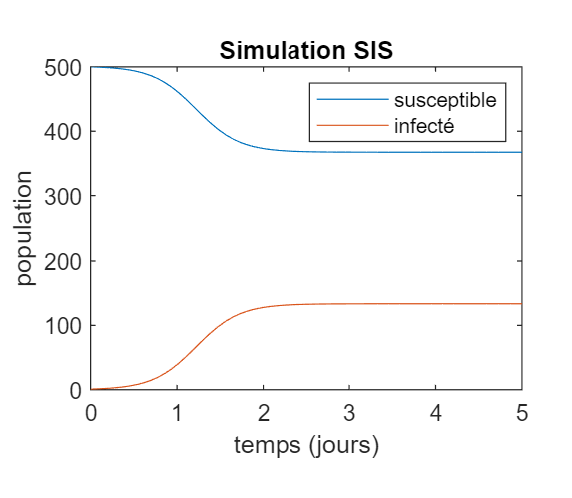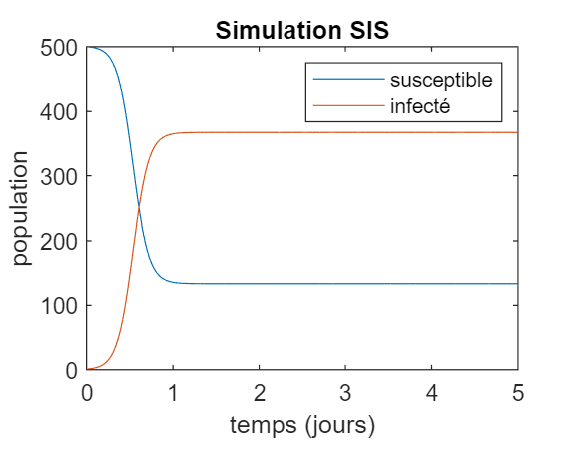

Interessons nous désormais à Beta (force de l'infection).

Nous remarquons que lorsque Beta est de plus en plus grand, la population infectée croit beaucoup et plus rapidement. Ainsi, à l'inverse de d et de lambda, beta est corrélé positivement à la population infectée.

Beta faible ( =5)                                                 Beta plus élevé (=17)

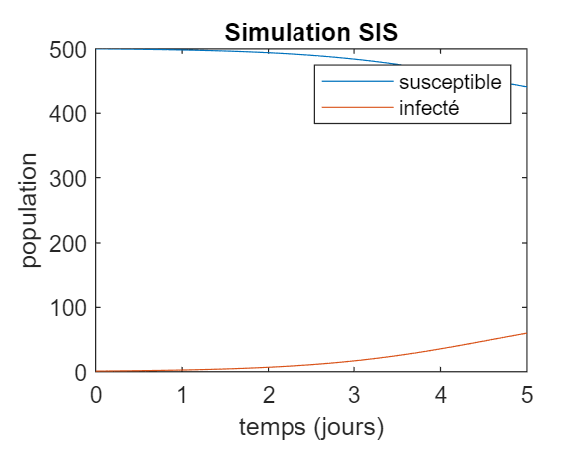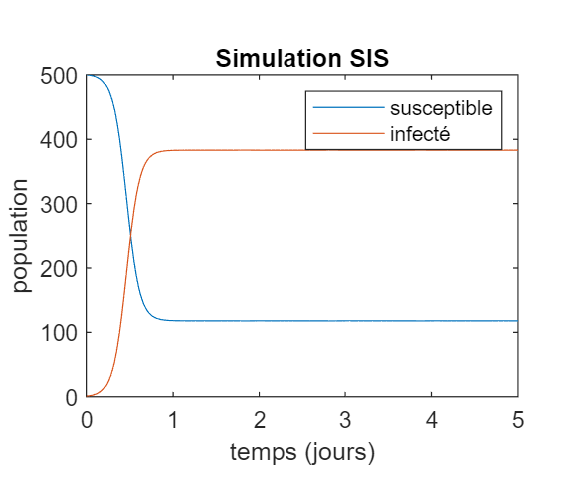

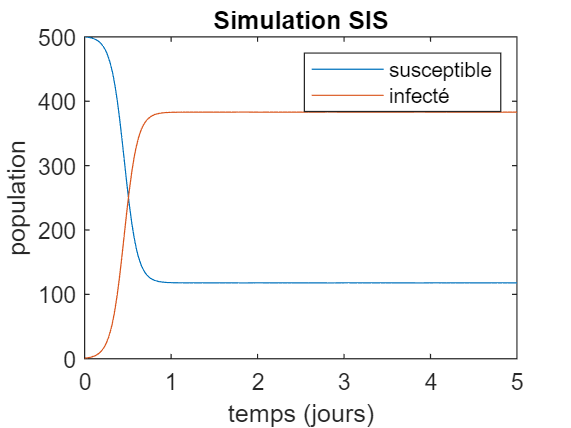

clear;
tRange=[0 5];
Y0=[500;1];
[tSol,YSol] = ode45(@SISmodel,tRange,Y0);

S = YSol(:,1);
I = YSol(:,2);

plot(tSol,S)
hold on
plot(tSol,I)

hold off
title("Simulation SIS");
xlabel('temps (jours)')
ylabel('population')
legend("susceptible","infecté")

2)Résoudre ce système à l'aide de simulink et étudier l'influence des paramètres sur le résultat.

Voir le simulink attaché. L'influence des paramètres est la même que dans la résolution MATLAB.

L'influence des paramètres est exactement la même.

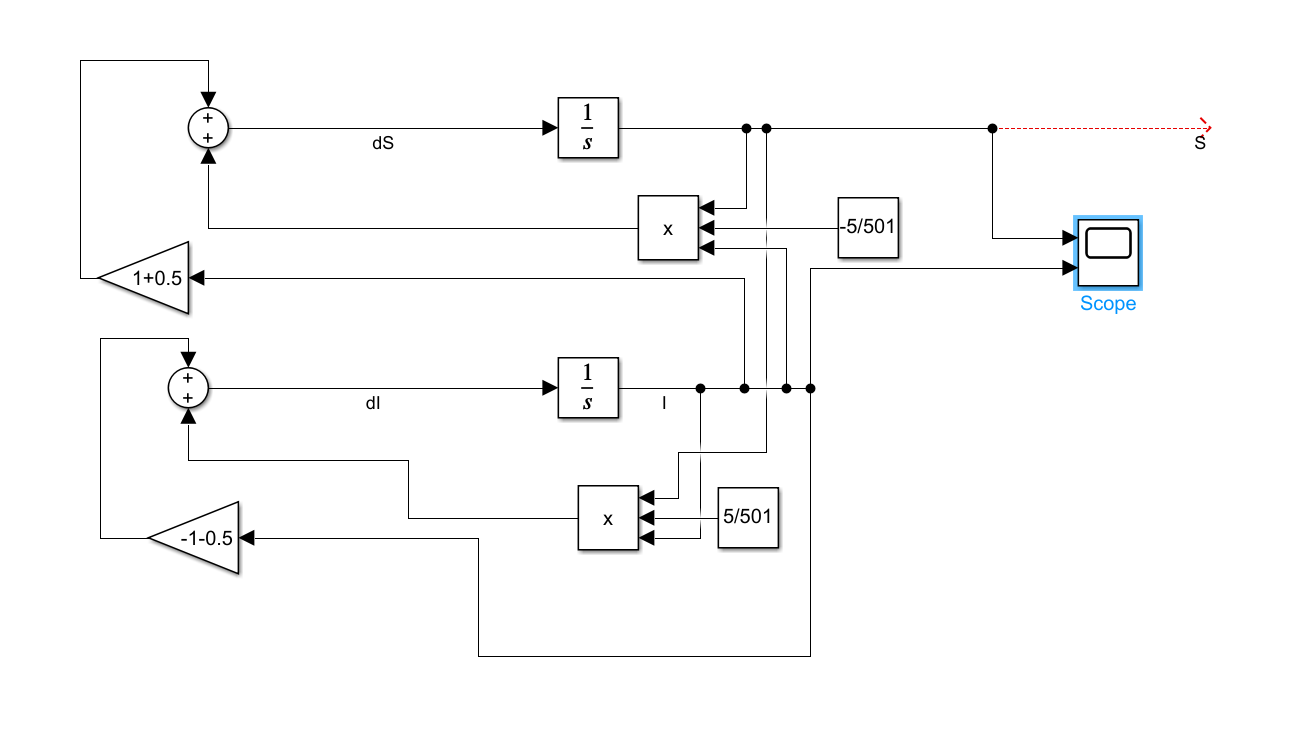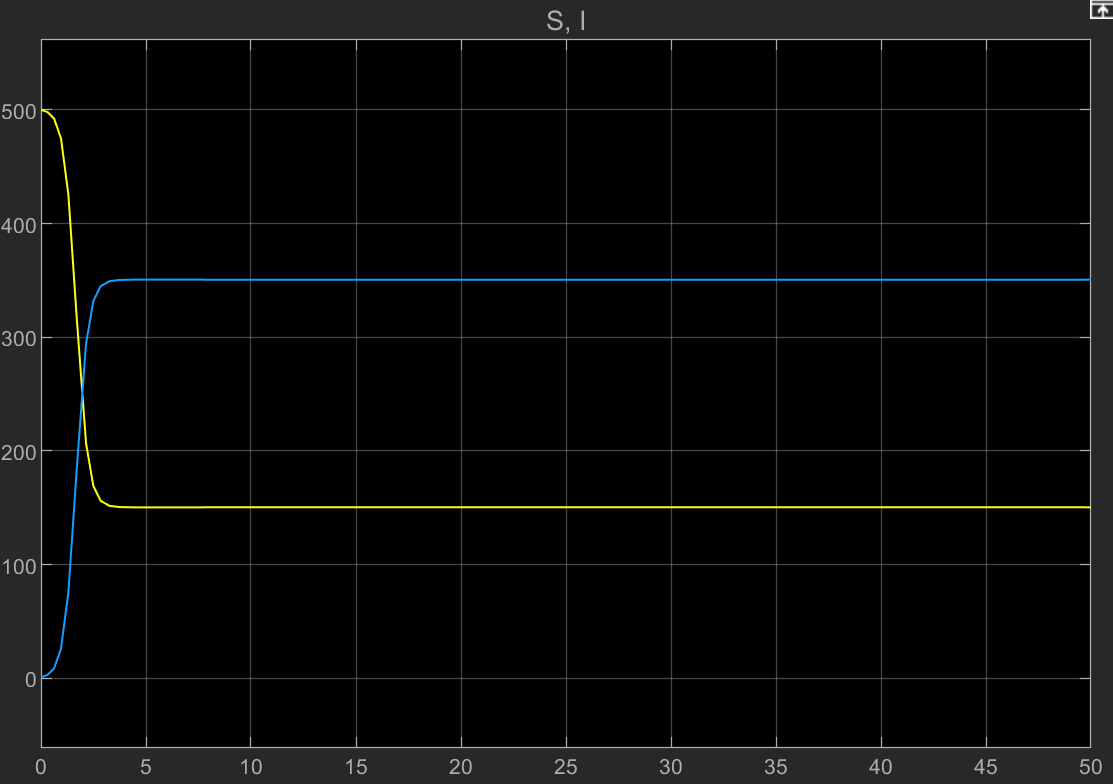

3)Comparer le résultat 1) et 2)

Dans le code Matlab et dans la representation Simulink, nous obtenons les mêmes resultats. Cela fait sens car dans l'un, nous posons les équations à l'écrit tandis que dans l'autre, nous les représentons à l'aide d'outils schématiques simples. Dans les 2 cas, nous pouvons simuler l'interface graphique ; l'un avec des plot et l'autre avec 2 scopes. Malgré tout, nous pouvons remarquer certaines très légères differences de précision au niveau des graphiques du aux divers outils utilisés.

4) Proposer une amélioration du modèle SIS et donner les résultats du nouveau modèle.

Dans un premier temps, interessons nous à un modèle très connu et bien plus utilisé que le modèle SIS dans la vie réelle ; le modèle SIR.

Ce modèle comporte 3 populations S (saine), I (inféctée), R (retirée), où beta représente le taux d'infection et lambda le taux de guerison. Par rapport au modèle SIS, il convient de bien différencier les personnes saines et les personnes retirées. En effet, les personnes saines n'ont pas encore été touchées par le virus tandis que les personnes retirées ne sont plus prises en compte.

Ainsi, le modèle SIR, bien que plus représentatif que le modèle SIS, ne s'occupe pas de prédire la mortalité de l'épidémie. Nous avons donc besoin de l'améliorer.

Le modèle SEIR est donc un peu plus puissant. Nous ajoutons encore une sous population, les populations infectées non-infectieuses (exposed en anglais). Elles ne sont pas contagieuses. Ainsi, nous pouvons prendre en compte a durée d'incubations gamma dans la fonction E(t).

A cela, comme dans le modèle SIS, nous ajoutons le taux de natalité n, puis le taux de mortalité mu de la population. Malgré tout, une personne peut décéder à tout état ; S,E,I et R.

**Voici ce que nous observons :**

Le taux de mortalité est supérieur au taux de natalité. En effet, la population saine en bleue diminue constamment. Les personnes non infectieuses en rouge possèdent un pic qui précède celui des personnes infectées infectieuses en jaune.

Enfin, après le pic de la courbe en jaune des personnes infectées infectieuses, la courbe décroit.

Bonus : Ajoutons finalement un taux de vaccination vax dans nos équations. Des personnes saines vont donc devenir directement retirées.

Nous observons donc un "saut" vers le haut de la courbe des retirées en violet, de meme pour la courbe bleue des personnes saines. La vaccination n'a aucun effet sur l'évolution de l'épidémie au niveau des personnes infectées bien qu'elle permette a des personnes saines de devenir directement retirées sans passer par la maladie.

Malgré la compléxité grandissante de ce système par rapport à celui du système SIS, d'autres paramètres nous échappent. En effet, à l'avenir, nous pourrions prendre en compte l'age des personnes.

Graph obtenu à beta = 0.01 | Lambda = 0.05 | n = 0.009 | mu=0.01 | vax=0.8 | gamma = 0.75

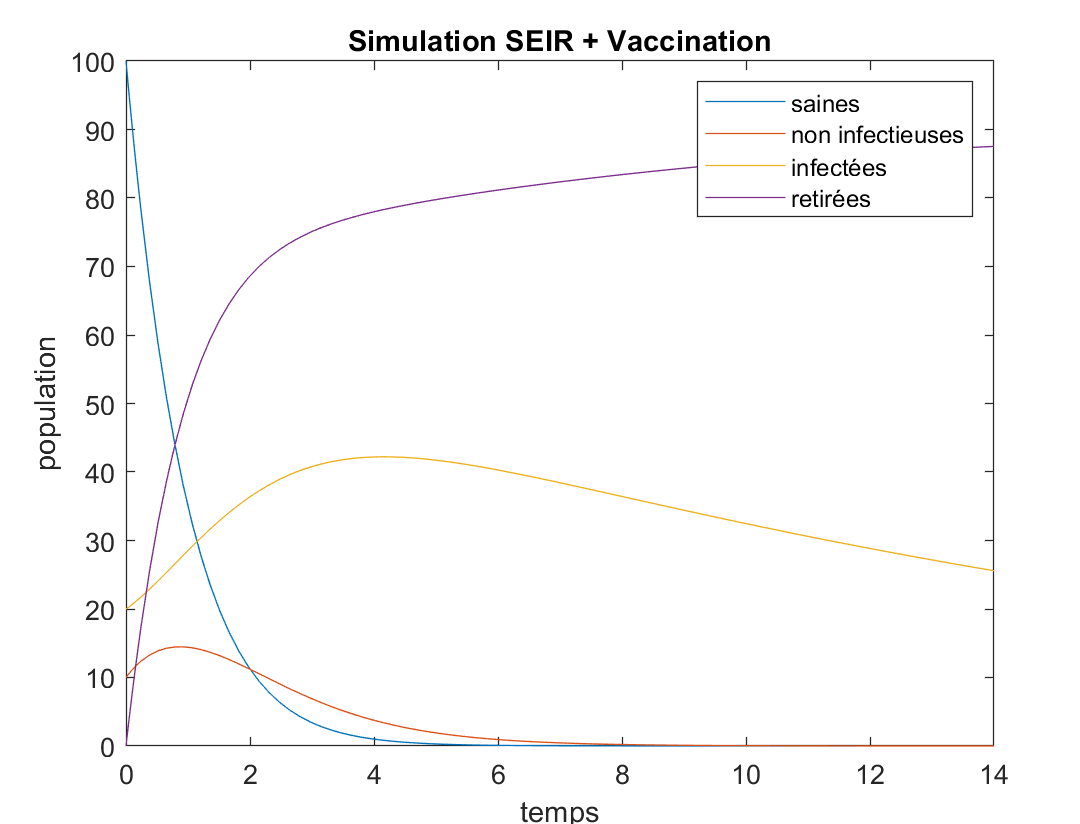

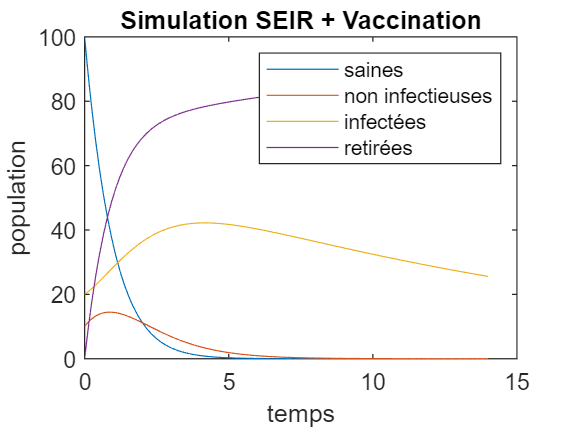


tRange = [0 14];
Y0 = [100;10 ; 20; 0];
[tSol,YSol] = ode45(@SEIRmodel,tRange,Y0);

S = YSol(:,1);
E=YSol(:,2);
I = YSol(:,3);
R = YSol(:,4);
plot(tSol,S)
hold on
plot(tSol,E)
plot(tSol,I)
plot(tSol,R)
hold off
title("Simulation SEIR + Vaccination");
xlabel('temps')
ylabel('population')
legend("saines","non infectieuses","infectées","retirées")

function dYdt = SEIRmodel(t,Y)  % TODO - Write the function declaration. Name the function SIRmodel
    % On extrait S, E, I et R du vecteur d'entrée Y
    S = Y(1); % susceptible / Saines
    E=Y(2);%Exposed / Personnes infectées non infectieuses
    I = Y(3); % infected / Infectées
    R = Y(4); % recovered / retirées
    
    % On défini les paramètres
    beta = 0.01;% force de l'infection
    lambda = 0.05; % param de guerison
    n=0.009;%taux de natalité
    mu=0.01;%taux de décès
    vax=0.8; %taux de vaccination
    gamma=0.75;%taux d'incubation
    % On définit dSdt, dIdt, dRdt et dEdt, les équations differentielles
    dSdt = -beta*S*I + n -mu*S-vax*S ;
    %E(t) personnes infectées non infectieuses
    dEdt=beta*S*I-gamma*E-mu*E;
    %Le produit IS mesure en quelque sorte les «rencontres» entre individus infectés et susceptibles. Cette équation est réglée par un paramètre b qui dépend en pratique de nombreux facteurs : contagiosité de la maladie, mesures de distanciation sociale, confinement.
    dIdt = gamma*E - lambda*I-mu*I;
    dRdt = lambda*I-mu*R+vax*S;
    %Cela signifie que le taux d'individus guéris varie proportionnellement au taux de personnes infectées
    % On creer le vecteur de sortie
    dYdt = [dSdt; dEdt; dIdt; dRdt];
end

function dYdt = SISmodel(t,Y)  %Fonction
    % Extraire S et I du vecteur d'entrée Y
    S = Y(1); % susceptible ou saine
    I = Y(2); % infecté
 
    
    % On défini les paramètres
    beta = 17;%force de l'infection / taux de contact
    N=S+I; % la population totale
    d=1; % taux naissance /deces
    lambda=3; %taux guerison

    % On définit dSdt et dIdt qui sont les équations differentielles du
    % système
    dSdt = -(beta*S*I)/N+(d+lambda)*I;
    dIdt = (beta*S*I)/N - (d+lambda)*I;
  
    
    % Créer le vecteur de sortie dYdt
    dYdt = [dSdt; dIdt];
end

